# **Fase 1: Modelado y caracterización de la planta en lazo abierto**

### **Ejercicio 1: Obtener la FdeT de la planta en lazo abierto.**

Después de realizar capturas del dispositivo con diferentes valores de entrada escalón, obtenemos la km y Tau de cada salida. Para ello, hemos desarrollado la función "valores_de_interes":

- Cargar el archivo .txt con los valores capturados.

- Representar la entrada escalón y la respuesta de la planta en lazo abierto.

- Recortar la señal de saliida.

- Ajustar la señal a 5 segundos.

- Hallar la km: Mediante la media de las últimas muestras.

- Hallar la Tau: Instante del tiempo en el que la señal vale el 63.2% de la km.

clear

format long
Ts = 35e-3;
fprintf('El periodo de muestreo es: %.4f s.\n', Ts)

El periodo de muestreo es: 0.0350 s.


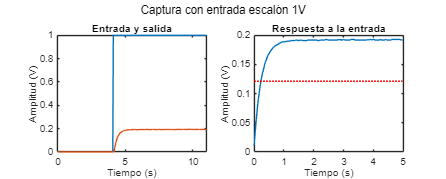

km con entrada escalón de 1V: 0.1920.
Tau con entrada escalón de 1V: 0.2625 s.



[km_1V, Tau_1V] = valores_de_interes('./Capturas/PGA_G4_1V.txt', Ts, 1);

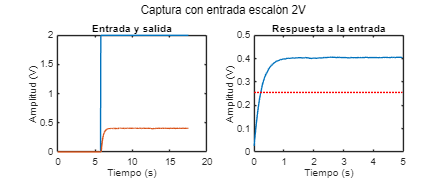

km con entrada escalón de 2V: 0.2030.
Tau con entrada escalón de 2V: 0.2625 s.



[km_2V, Tau_2V] = valores_de_interes('./Capturas/PGA_G4_2V.txt', Ts, 2);

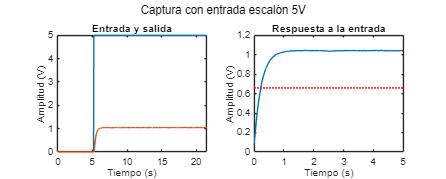

km con entrada escalón de 5V: 0.2079.
Tau con entrada escalón de 5V: 0.2625 s.



[km_5V, Tau_5V] = valores_de_interes('./Capturas/PGA_G4_5V.txt', Ts, 5);

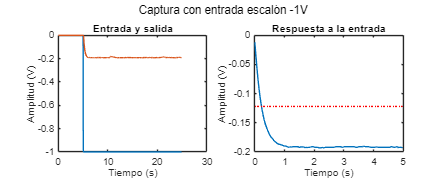

km con entrada escalón de -1V: 0.1925.
Tau con entrada escalón de -1V: 0.2625 s.



[km_n1V, Tau_n1V] = valores_de_interes('./Capturas/PGA_G4_n1V.txt', Ts, -1);

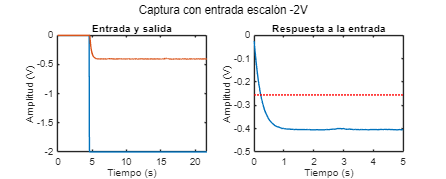

km con entrada escalón de -2V: 0.2023.
Tau con entrada escalón de -2V: 0.2625 s.



[km_n2V, Tau_n2V] = valores_de_interes('./Capturas/PGA_G4_n2V.txt', Ts, -2);

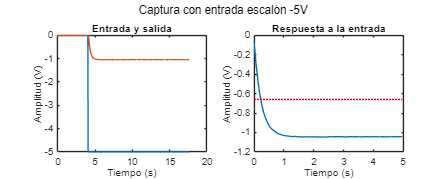

km con entrada escalón de -5V: 0.2087.
Tau con entrada escalón de -5V: 0.2625 s.



[km_n5V, Tau_n5V] = valores_de_interes('./Capturas/PGA_G4_n5V.txt', Ts, -5);

Después, hacemos la media de las kms y Taus para obtener de forma más precisa la km y Tau del sistema:

km = mean([km_1V (km_2V) (km_5V) (km_n1V) (km_n2V) (km_n5V)]);
Tau = mean([Tau_1V Tau_2V Tau_5V Tau_n1V Tau_n2V Tau_n5V]);

fprintf('La km de la planta es: %.4f.\n', km)

La km de la planta es: 0.2011.


fprintf('La Tau de la planta es: %.4f s.\n', Tau)

La Tau de la planta es: 0.2625 s.


Finalmente, sustituimos para obtener la FdeT de la planta:

Gs = tf(km, [Tau 1])


Gs =
 
     0.2011
  ------------
  0.2625 s + 1
 
Continuous-time transfer function.
Model Properties



$$G(s) = \frac{km}{Tau \cdot s + 1} = \frac{0.2011}{0.2625s + 1} [\frac{m/s}{V}]$$


p = pole(Gs);
fprintf('El polo de la planta es: %.4f.\n', p)

El polo de la planta es: -3.8095.



ts = -3/p;
fprintf('El tiempo de establecimiento de la planta es: %.4f.\n', ts)

El tiempo de establecimiento de la planta es: 0.7875.


### Ejercicio 2: Validar el modelo mediante Simulink.

Comprobar que para todas las capturas realizadas, el modelo coincide con el valor obtenido:

%open_system('modeloFdeT.slx')

### Ejercicio 3: Modelación de la saturación y la zona muerta.

#### Saturación: 

Se produce con entrada escalón = ±10V.

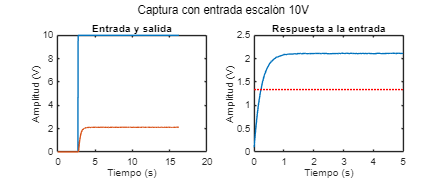

km con entrada escalón de 10V: 0.2109.
Tau con entrada escalón de 10V: 0.2625 s.


[km_10V, Tau_10V] = valores_de_interes('./Capturas/PGA_G4_10V.txt', Ts, 10);

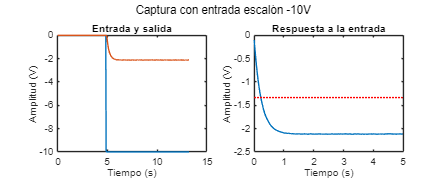

km con entrada escalón de -10V: 0.2114.
Tau con entrada escalón de -10V: 0.2625 s.


[km_n10V, Tau_n10V] = valores_de_interes('./Capturas/PGA_G4_n10V.txt', Ts, -10);

#### Zona muerta:

El último valor con el que se está en la zona muerta es cuando la entrada escalón vale ±0.19V.

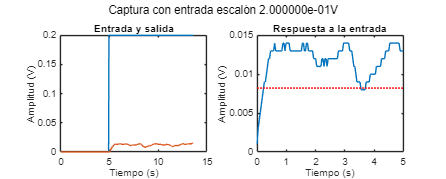

km con entrada escalón de 2.000000e-01V: 0.0625.
Tau con entrada escalón de 2.000000e-01V: 0.2275 s.


%[km_0_19V, Tau_0_19V] = valores_de_interes('./Capturas/PGA_G4_0.19V.txt', Ts, 0.19);
[km_0_20V, Tau_0_20V] = valores_de_interes('./Capturas/PGA_G4_0.2V.txt', Ts, 0.20);

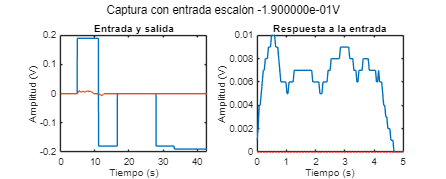

km con entrada escalón de -1.900000e-01V: -0.0184.
Tau con entrada escalón de -1.900000e-01V: 0.0875 s.



[km_0_n19V, Tau_n0_19V] = valores_de_interes('./Capturas/PGA_G4_n0.19V.txt', Ts, -0.19);

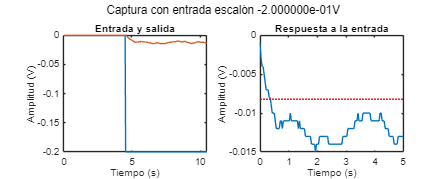

km con entrada escalón de -2.000000e-01V: 0.0650.
Tau con entrada escalón de -2.000000e-01V: 0.4025 s.


[km_0_n20V, Tau_n0_20V] = valores_de_interes('./Capturas/PGA_G4_n0.2V.txt', Ts, -0.20);

#### Modelo Simulink:

%open_system('modeloSatDead.slx')

### Ejercicio 4: Equivalente discreto en régimen permanente y transitorio.

#### Equivalente discreto:

BoG = c2d(Gs, Ts, 'zoh')


BoG =
 
    0.0251
  ----------
  z - 0.8752
 
Sample time: 0.035 seconds
Discrete-time transfer function.
Model Properties



$$BoG(z) = \frac{0.0251}{z - 0.8752} [\frac{m/s}{V}]$$


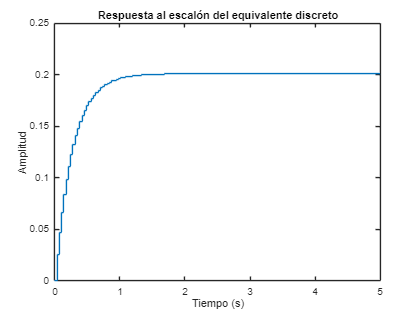

figure
[c, t] = step(BoG,5); % Obtener la respuesta al escalón en un intervalo de 5 segundos
stairs(t, c); % Primero el tiempo, luego la señal 
title('Respuesta al escalón del equivalente discreto'); 
xlabel('Tiempo (s)'); 
ylabel('Amplitud');
xlim([0 5]);

#### Régimen permanente:

La planta es de tipo 0.


$$k_o[BoG] = \lim_{z \to 1} \frac{0.0251}{z - 0.8752} = 0.20112$$


#### Régimen transitorio: 

Polo real simple -> Sistema sobreamortiguado.


$$p = 0.8752$$



$$ks = \frac{-3}{ln(|p|)} = \frac{-3}{ln(0.8752)} = 22.505 = 23$$



$$ts = ks \cdot Ts = 0.805 s$$
 

### Ejercicio 5: Respuesta de la planta en régimen permanente para ±1V con perturbación (10 personas = 700 kg).

En las siguientes capturas, podemos observar como la salida se mantiene normal hasta que se activa la perturbación:

- En el caso de la entrada escalón 1V, se puede ver que cuando se activa la perturbación, como esta vale 0.2V, se resta y la salida es 0V.

- En el caso de la entrada escalón -1V, se puede observar que cuando se activa la perturbación, esta se resta, por lo que la salida vale -0.4V.

Esto tiene sentido dado que cuando las escaleras suben (Tensión positiva), las personas producen una perturbación sustractiva y la escalera necesita más tensión para subir, mientras que cuando las escaleras bajan (Tensión negativa), el peso de las personas aumenta la velocidad de bajada (Obviar la línea en las "Respuesta a la entrada"). 

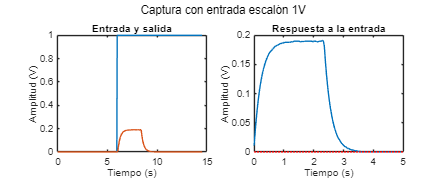

km con entrada escalón de 1V: 0.0575.
Tau con entrada escalón de 1V: 0.0875 s.


[km_1V_10P, Tau_1V_10P] = valores_de_interes('./Capturas/PGA_G4_1V_10P.txt', Ts, 1);

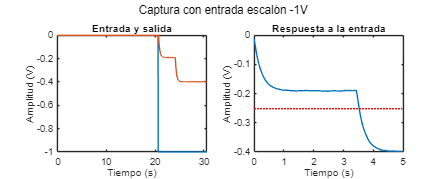

km con entrada escalón de -1V: 0.3980.
Tau con entrada escalón de -1V: 3.5525 s.


[km_n1V_10P, Tau_n1V_10P] = valores_de_interes('./Capturas/PGA_G4_n1V_10P.txt', Ts, -1);

#### Modelo en Simulink:

%open_system('modeloPerturbacion.slx')